% Niranjan Mathirajan, Owen Davis
% December 12, 2025
% Phased Array Spacing Playground
% Source 1: https://innovationspace.ansys.com/courses/wp-content/uploads/sites/5/2022/07/AntennaArrays_04ManipulatingtheArrayFactor.pdf
% Source 2: https://www.antenna-theory.com/arrays/arrayfactor.php
% Source 3: https://www.antenna-theory.com/definitions/wavevector.php


% Some notes about the simulation:
% the phase factor should always assume ideal spacing, as the computer
% doesn't know about the error in spacing. This is why the simulation and
% calculation's spacing don't incorporate the actual spacing, rather the
% ideal
%
% The expected calculation should never use the actual spacing, just ideal
% and error. The whole point is that the expected value incorporates the
% ideal distribution of dx_error (uniform), so that we can calculate the
% true error.
clc;

% -- constants --
T = 100; % number of trials performed
f = 5e6; % frequency of antenna (Hz)
c = 3e8; % speed of light (m/s)
lambda = c/f; % wavelength (m)
k = 2 * pi/lambda; % 1-D wave vector, see source (3) (rad/m)

% -- array parameters --
N = 17; % number of antennas
nTheta = 180;
theta = linspace(-pi/2, pi/2, nTheta); % range of angles the array "sees"
steerAngle = 0 * pi/180; % steering angle of array
dx_ideal = 1 * lambda; % expected distance between antennas
dx_error = 0.1* lambda; % max variation in spacing

phase = -k * dx_ideal * cos(steerAngle); % term added to each AF to aim beam
measure_angle_deg = -10; % angle we measure AF at (range from 1 to 90)
measure_angle_rad = measure_angle_deg * 2*pi / 360;

% --- Monte Carlo Simulation ---

simulated_average = zeros(T,1);
for i = 1:T
    AF = zeros(nTheta,1);
    % --- get position errors (non-cumulative) ---
    dx_actual = zeros(N,1);
    for n = 1:N
        dx_actual(n) = -dx_error + 2*dx_error*rand();
    end
    
    % --- get Array Factor for every angle
    for t = 1:nTheta
        for n = 1:N
            % AF equation from source (1):
            main_term = k*cos(theta(t))*((n-1)*dx_ideal + dx_actual(n));
            phase_term = -(n-1)*k*dx_ideal*cos(steerAngle);
            AF(t) = AF(t) + exp(1j*(main_term + phase_term));
        end
    end
    simulated_average(i) = AF(measure_angle_deg+90)/N;
end

simulated_avg = abs(mean(simulated_average));


% --- Expected calculation ---

E = 0;
for n = 1:N
    m = n-1;
    % these terms were pulled out of the array factor, should match
    % previous.
    main_term = exp(1j*k*m*cos(measure_angle_rad)*dx_ideal);
    phase_term = exp(-1j*k*m*dx_ideal*cos(steerAngle));
    random_variable = (exp(1j*k*cos(measure_angle_rad)*dx_error) ...
            - exp(1j*k*cos(measure_angle_rad)*-1*dx_error))/(1j*k*cos(measure_angle_rad)*2*dx_error);
    E = E + (main_term * phase_term * random_variable);
end
Expected = abs(E)/N 

Expected = 0.8382


E_2 = 0;
for n= 1:N
    for m = 1:N
        main_term = exp(1j*k*dx_ideal*cos(measure_angle_rad)*(n-m));
        phase_term = exp(-1j*k*dx_ideal*cos(steerAngle)*(n-m));
        if n == m
            % Diagonal: error_n - error_n = 0, so exp(0) = 1
            random_variable = 1;
        else
            random_variable_n = (exp(1j*k*cos(measure_angle_rad)*dx_error) ...
            - exp(1j*k*cos(measure_angle_rad)*-1*dx_error))/(1j*k*cos(measure_angle_rad)*2*dx_error);
            random_variable_m = (exp(-1j*k*cos(measure_angle_rad)*dx_error) ...
            - exp(1j*k*cos(measure_angle_rad)*dx_error))/(-1j*k*cos(measure_angle_rad)*2*dx_error);

            random_variable = random_variable_n*random_variable_m;
        end

        E_2 = E_2 + (main_term * phase_term * random_variable);
    end
end

Var = (abs(E_2))/N^2 - abs(E/N)^2

Var = 0.0071

var(simulated_average)

ans = 0.0071


disp(simulated_avg)

    0.8111



disp(abs(E)/N)

    0.8382



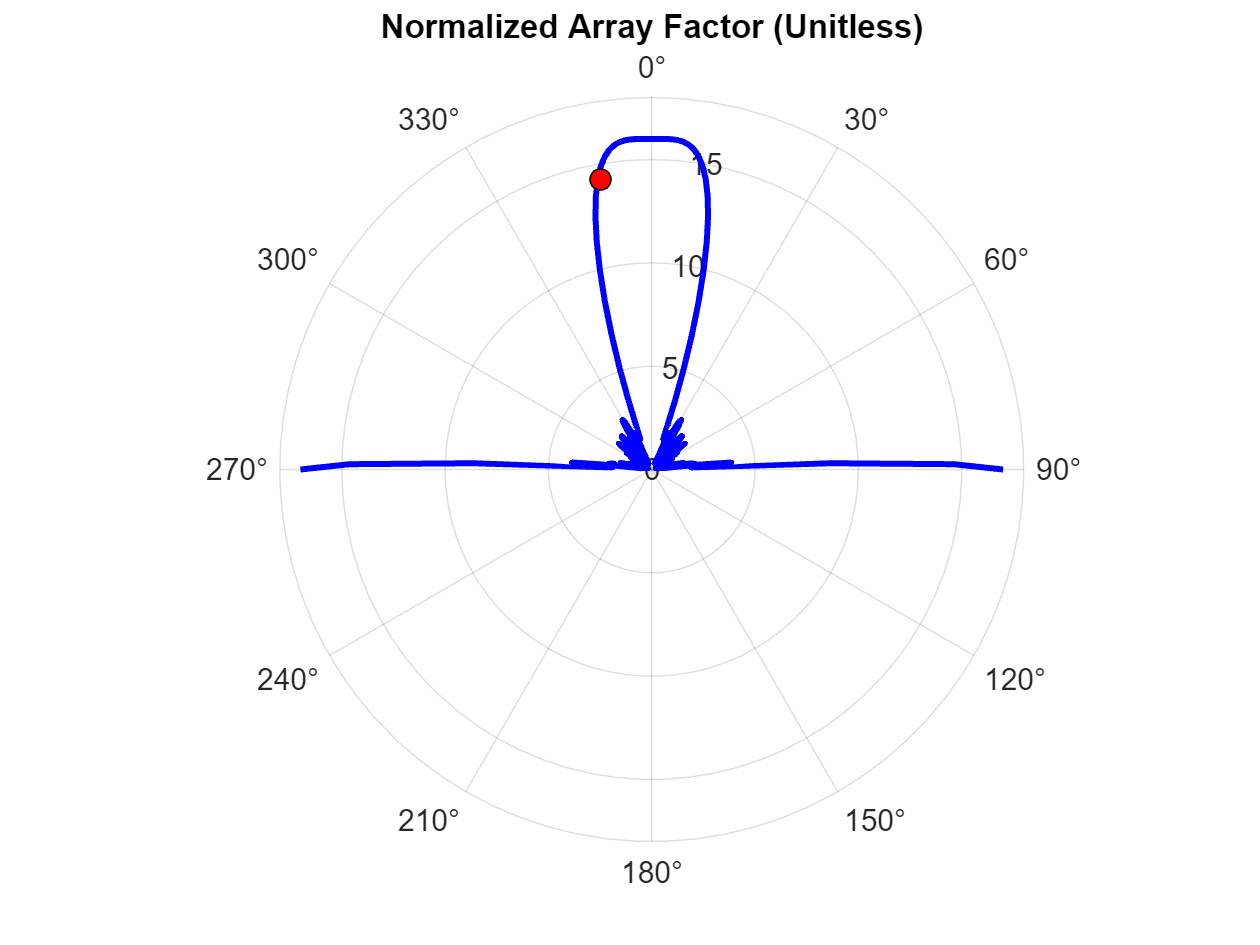


% -- plotting --
figure;
hps = polaraxes;
polarplot(theta, abs(AF),"blue", 'LineWidth',2); % plot AF
hold on;
% place dot on AF at our measure angle
polarplot(measure_angle_rad, abs(AF(measure_angle_deg + 90)), 'o', 'MarkerSize', 7, 'MarkerFaceColor', 'r', 'MarkerEdgeColor','black');
hps.ThetaZeroLocation = 'top'; % make 0 degrees show up at top of plot
ax = gca;
hps.ThetaDir = 'clockwise';
gca.FontSize = 12;
title('Normalized Array Factor (Unitless)');
grid on;

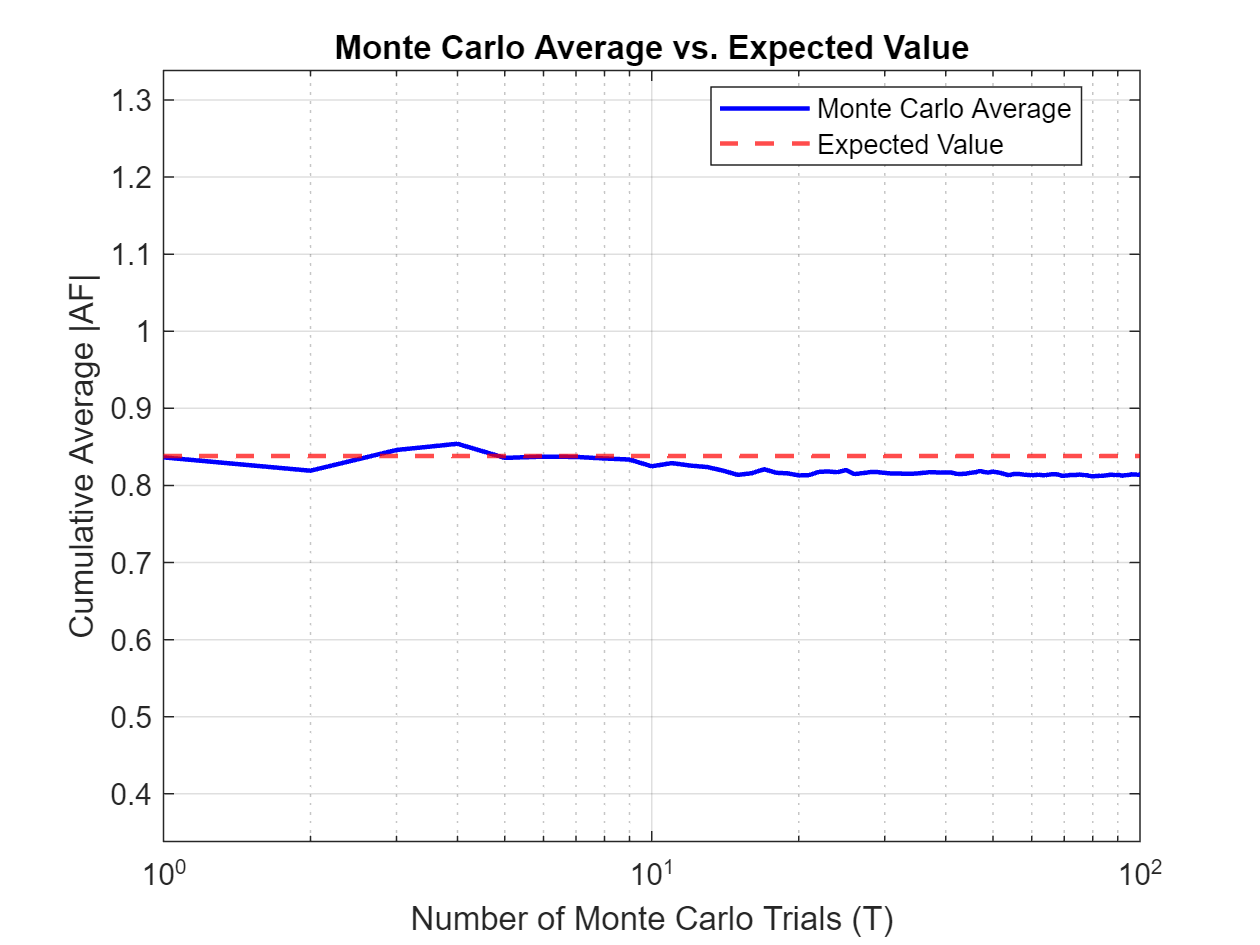



% -- plotting Error vs Trials --
figure;
% Calculate cumulative average as T increases
cumulative_avg = cumsum(abs(simulated_average)) ./ (1:T)';
semilogx(1:T, cumulative_avg, 'b', 'LineWidth', 1.5); % Changed to semilogx for log scale on x-axis
hold on;
% Add horizontal line at the expected calculated average
yline(Expected, 'r--', 'LineWidth', 1.5);
xlabel('Number of Monte Carlo Trials (T)');
ylabel('Cumulative Average |AF|');
title('Monte Carlo Average vs. Expected Value');
legend('Monte Carlo Average', 'Expected Value', 'Location', 'best');
grid on;
% Center the plot on Expected with a range of 1
ylim([Expected - 0.5, Expected + 0.5]);
xlim([1 T]); % Ensure x-axis shows full range